%Forrás: https://www.mathworks.com/help/nav/ug/train-deep-learning-based-sampler-for-motion-planning.html

close all
clear all
%Egyik feltételezés:
%Use the Network property to store a deep neural network that you can use to find state space samples in an unknown or known environment. You can then use the selected samples for motion planning using different path planners.
%Tehát most betanítjuk azon, amiina tutorialbaa majd a sajátunkra
%alkalmazzuk

if ~exist("mazeMapDataset.mat","file")
    datasetURL = "https://ssd.mathworks.com/supportfiles/nav/data/mazeMapDataset.zip";
    websave("mazeMapDataset.zip", datasetURL);    
    unzip("mazeMapDataset.zip")    
end

% Load the maze map dataset
load("mazeMapDataset.mat", "dataset", "stateSpace");
head(dataset)

             Map                  Path     
    ______________________    _____________

    1×1 binaryOccupancyMap    {14×3 single}
    1×1 binaryOccupancyMap    { 8×3 single}
    1×1 binaryOccupancyMap    {24×3 single}
    1×1 binaryOccupancyMap    {23×3 single}
    1×1 binaryOccupancyMap    {17×3 single}
    1×1 binaryOccupancyMap    {15×3 single}
    1×1 binaryOccupancyMap    { 7×3 single}
    1×1 binaryOccupancyMap    {10×3 single}



**Create Motion Planning Networks**

mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];


**Prepare Data for Training**

split = 0.8;
trainData = dataset(1:split*end,:);
validationData = dataset(split*end+1:end,:);

dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);


Tanítása

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:30        0.001                            50.153
            1        1       00:00:30        0.001          50.302                  
           50        1       00:00:37        0.001         0.53892                  
          100        1       00:00:41        0.001         0.26769                  
          150        1       00:00:44        0.001         0.18789                  
          200        1       00:00:48        0.001         0.14953                  
          250        1       00:00:51        0.001         0.12016                  
          300        1       00:00:55        0.001        0.099005                  
          350        1       00:00:58        0.001         0.08382                  
          400        1       00:01:02        0.001         0.0733

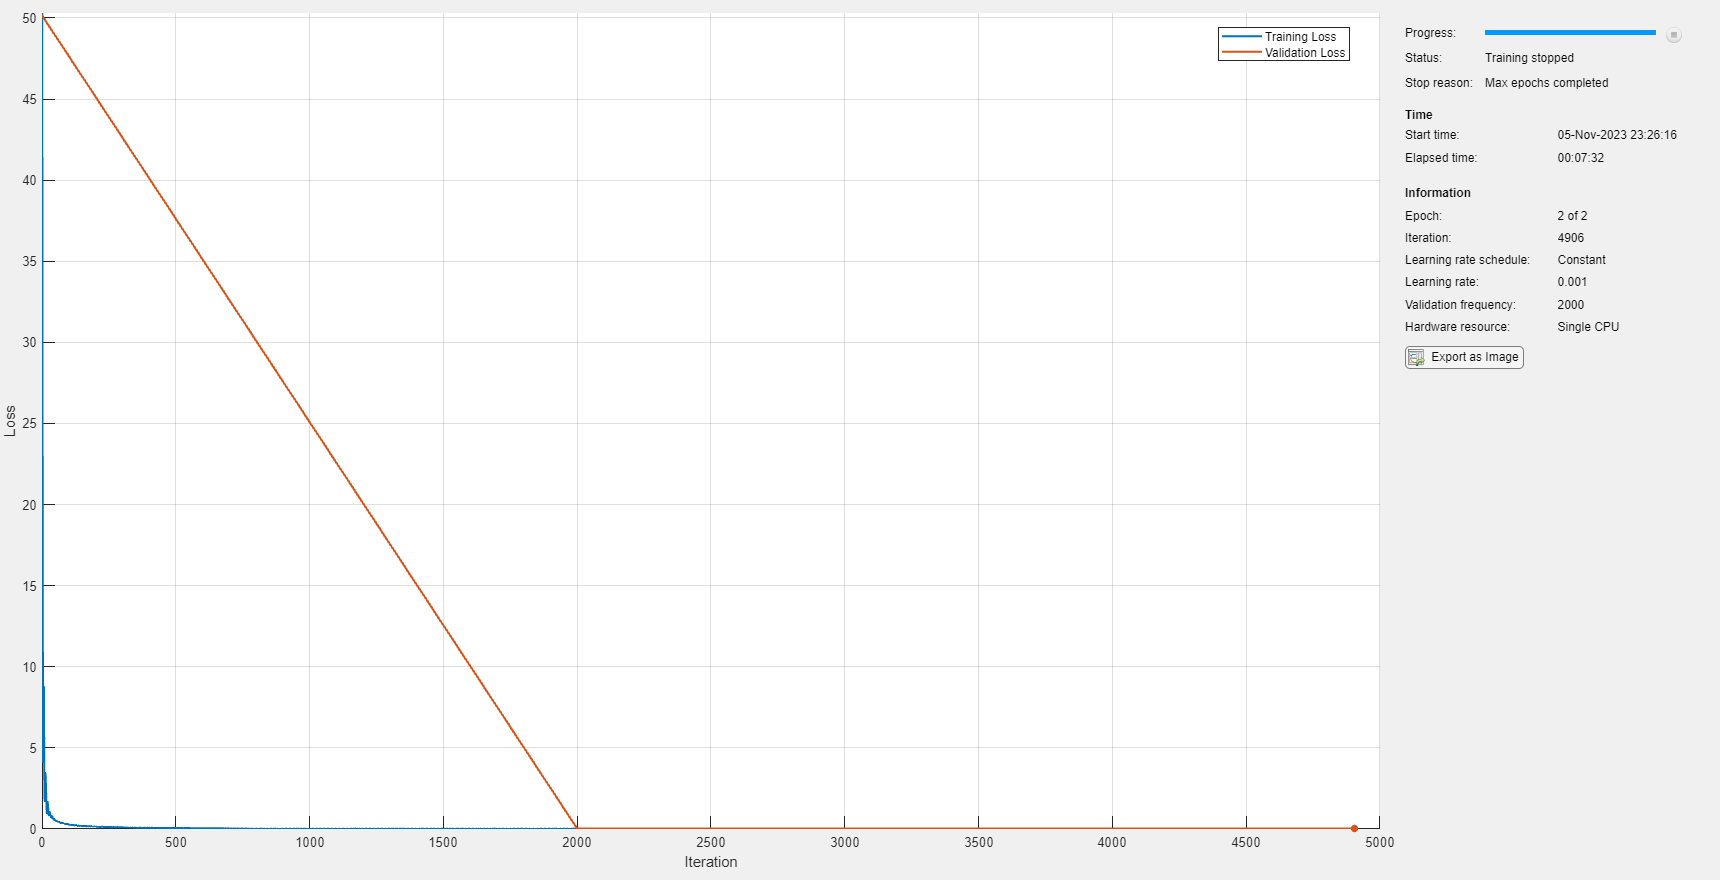

info =   TrainingInfo with properties:

           TrainingHistory: [4906×4 table]
         ValidationHistory: [4×2 table]
    OutputNetworkIteration: 4906
                StopReason: "Max epochs completed"


doTraining = true;
if doTraining
    options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=2,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=2000,...
        Plots="training-progress");

    % Train network
    [net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);
    
    % Update Network property of mpnet object with net
    mpnet.Network = net;
    info
end

Megnézzük mi van benne

mpnet

mpnet =   mpnetSE2 with properties:

     StateBounds: [3×2 double]
     LossWeights: [100 100 0]
    EncodingSize: [9 9]
       NumInputs: 89
      NumOutputs: 4
         Network: [1×1 dlnetwork]


mpnet.Network

ans =   dlnetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
    Connections: [11×2 table]
     Learnables: [10×3 table]
          State: [0×3 table]
     InputNames: {'input'}
    OutputNames: {'output'}
    Initialized: 1

  View summary with summary.
